# Project: Beam and Ball

## System's Transfer function

m = 0.002;
r = 0.04;
d = 0.097;
L = 0.25;
I = (2 * m * (r^2))/5;
theta = pi/6;
k = d/L;
g = 9.81;

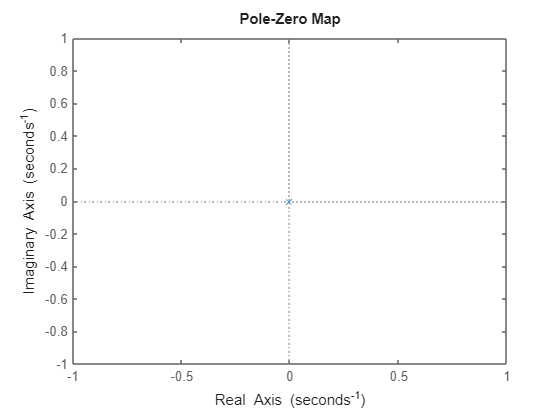

num = [0 0 -m*g*k];
den = [m + I/r^2 0 0];
TF = tf(num, den);
pzmap(TF)

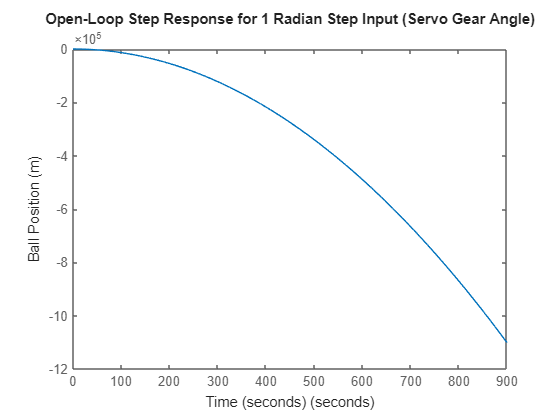

step(TF)
title('Open-Loop Step Response for 1 Radian Step Input (Servo Gear Angle)')
xlabel('Time (seconds)')
ylabel('Ball Position (m)')

# Task 3: Controller responses

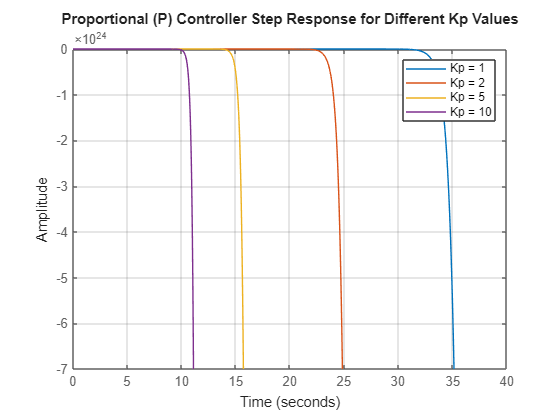

Kp_range = [1, 2, 5, 10];
Kd_range = [0.1, 0.5, 1, 2];
Ki_range = [0.1, 1, 2, 5];

figure;
hold on;
for i = 1:length(Kp_range)  
    P_TF = pid(Kp_range(i));
    sys_P = feedback(P_TF * TF, 1);
    step(sys_P);
end

title('Proportional (P) Controller Step Response for Different Kp Values');
legend(arrayfun(@(Kp) sprintf('Kp = %d', Kp), Kp_range, 'UniformOutput', false));
grid on;
hold off;

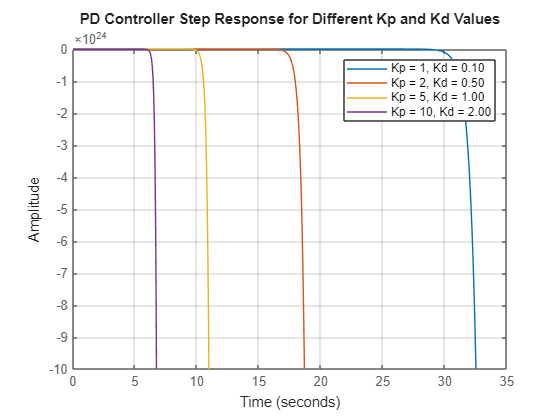

figure;
hold on;
for i = 1:length(Kp_range)  
    PD_TF = pid(Kp_range(i), 0, Kd_range(i));
    sys_PD = feedback(PD_TF * TF, 1);
    step(sys_PD);
end

title('PD Controller Step Response for Different Kp and Kd Values');
legend(arrayfun(@(Kp, Kd) sprintf('Kp = %d, Kd = %.2f', Kp, Kd), Kp_range, Kd_range, 'UniformOutput', false));
grid on;
hold off;

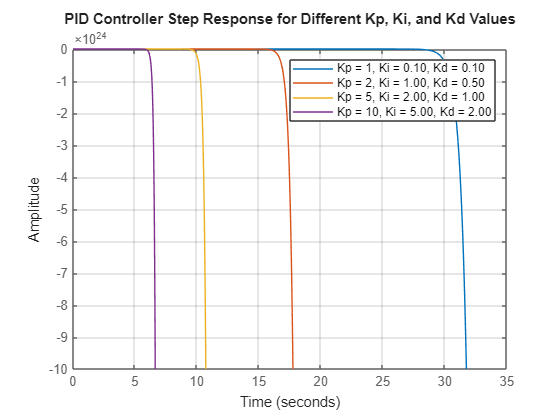

figure;
hold on;
for i = 1:length(Kp_range)  
    PID_TF = pid(Kp_range(i), Ki_range(i), Kd_range(i));
    sys_PID = feedback(PID_TF * TF, 1);
    step(sys_PID);
end

title('PID Controller Step Response for Different Kp, Ki, and Kd Values');
legend(arrayfun(@(Kp, Ki, Kd) sprintf('Kp = %d, Ki = %.2f, Kd = %.2f', Kp, Ki, Kd), Kp_range, Ki_range, Kd_range, 'UniformOutput', false));
grid on;
hold off;